clear all; close all; clc;

threshold = 0.002;
pixel_observation_x = 212

pixel_observation_x = 212

pixel_observation_y = 120

pixel_observation_y = 120

sample_count =199

sample_count = 199

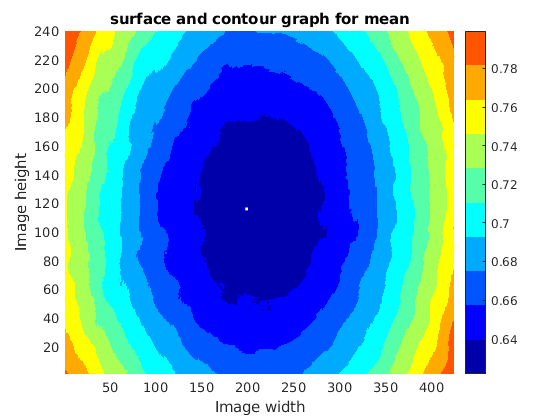

width = 424;
height = 240;
path_pefix ="/home/sur/catkin_ws/src/d435_characterization/rosbag/carpet/carpet_wo_glare/beforeCSV_file_for_cloud_";
path_postfix = ".csv";

sample_vector_truth = zeros(sample_count,1);

for callback_count = 1:sample_count
    
    h = string(callback_count);
    path = path_pefix+h+path_postfix;
    data = csvread(path);
    
    matrix_mean = zeros(height,width);
    avg_mean_col = data(:,4);
    
    i=1;
    for cImage_x = 1:height
        for rImage_y = 1:width
            matrix_mean(cImage_x,rImage_y) = avg_mean_col(i);          
            i = i+ 1;
        end
    end
    v = matrix_mean(pixel_observation_x,pixel_observation_y);
    
    sample_vector_truth(callback_count) = v;
    
    if(callback_count<=2)
        % surfc for the mean
        x = 1:width;
        y = 1:height;
        z = matrix_mean;
        [X1,X2]=meshgrid(x,y);
        surfc(X1,X2,z)
        
        grid on
        view(2)
        title('surface and contour graph for mean')
        xlabel('Image width')
        ylabel('Image height')
        zlabel('mean')
        shading interp
        colormap (jet(10))
        colorbar
        saveas(gcf,'image_map_for_callback_0_.png')
        
    end
end


sample_vector_truth

sample_vector_truth =     0.6817
    0.6828
    0.6828
    0.6807
    0.6817
    0.6839
    0.6817
    0.6839
    0.6828
    0.6828


mean = mean(sample_vector_truth)

mean = 0.6826

p = 0;

for i = 1:sample_count
    if((sample_vector_truth(i)-mean)^2<threshold^2)
        p=p+1;
    end
end

prob_of_sucess = p/sample_count

prob_of_sucess = 0.9698


sample_mean = p;
sample_std = sqrt((p/sample_count)*(1-p/sample_count))

sample_std = 0.1710

sampling_dist_mean = sample_mean;
sampling_dist_std = sample_std/sqrt(sample_count);

z_95_per = 2.58;

lower_limit_percentage = -1*(z_95_per)*sampling_dist_std+sample_mean/sample_count

lower_limit_percentage = 0.9386

upper_limit_percentage = (z_95_per)*sampling_dist_std+sample_mean/sample_count

upper_limit_percentage = 1.0011